# Project 2: Malaria Dectection on Cell Images (CNN Architecture)

**ECE 595**

**Author**: Connor Prikkel*

*: (Based on the previous work of Barath Narayanan Narayanan, Redha Alia, Russell C. Hardie)

**Date**: 11/25/23

The plasmodium malaria dataset is downloaded and loaded into MATLAB. Each image's label is tallied and tracked; the dataset is split into training, test, and validation datasets following Dr. Narayanan's approach.

% Clean up workspace
close all; clear; clc;

% Images datapath – Please modify your path accordingly
datapath='D:\Connor\ECE 595\Project 2\cell_images\cell_images';

% Image datastore
img_datastore = imageDatastore(datapath, ...
'IncludeSubfolders',true, ...
'LabelSource','foldernames');

% Determine amount of each label
total_split = countEachLabel(img_datastore)

total_split = 2×2 table
       Label       Count
    ___________    _____

    Parasitized    13779
    Uninfected     13779


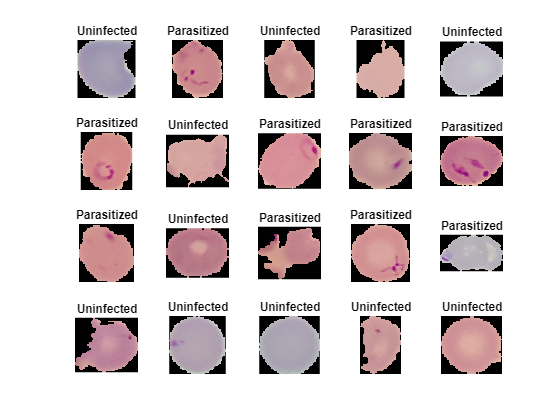


% Store labels in a variable
labels = img_datastore.Labels;

% Can use built in methods that are part of Deep Learning toolbox and discussed in paper

% Split the data into training and testing datasets
train_percent = 0.8;
[img_train,img_test] = splitEachLabel(img_datastore, train_percent, 'randomize');

% Further split the training dataset in half to form the validation dataset
valid_percent = 0.1;
[img_valid, img_train] = splitEachLabel(img_train, valid_percent, 'randomize');

train_split=countEachLabel(img_train);

% Visualize part of the dataset to ensure correctly loaded

% Count number of train labels
num_train_images = length(img_train.Labels);

% Randomly pick 20 images (from training subset)
perm = randperm(num_train_images,20);

figure;
for idx=1:20

 subplot(4,5,idx);
 imshow(imread(img_train.Files{perm(idx)}));
 title(sprintf('%s',img_train.Labels(perm(idx))))

end

## CNN Architecture without Preprocessing

### CNN Architecture Design

The CNN arhitecture that the data will be inputted into is now defined. Unlike the previous approach, the size of the input images is increased before being inputted into the CNN. To compensate for this, the filter size is slightly increased to 5 x 5. This will help the CNN in classifying the cases where the parasites are larger and allows the network to achieve a similar accuracy to a network using a smaller filter size. 

Since each filter covers more pixels, average pooling layers are used in place of max pooling layers. In order to avoid learning too many parameters, the number of filters in the first convolutional layer is halved from the eight used before to 4. Each layer still uses double the number of filters as the previous layer, but this approach utilizes 7 convolutional layers instead of 6 in order to achieve comprable accuracy for starting with less filters.

% Define image size and reshape them
img_size = [200 200];

img_train.ReadFcn=@(filename)reshape_image(filename, img_size);
img_valid.ReadFcn=@(filename)reshape_image(filename, img_size);
img_test.ReadFcn=@(filename)reshape_image(filename, img_size);  

% Define the CNN's layers
layers=[

    % Input Image Layer
    imageInputLayer([img_size,3])
    
    % 2-D Convolution Layer of size 5 x 5 and 4 filters with Same Padding
    % (Increased number of filters)
    convolution2dLayer(5, 4, 'Padding', 'same');
    % batch Normalization layer to ease the process for gradient descent
    batchNormalizationLayer
    % ReLU Activation Layer
    reluLayer
    % Avg Pooling Layer of Size 2 x 2 with a Stride of 2
    averagePooling2dLayer(2,'Stride',2)
    
    % 2-D Convolution Layer of size 5 x 5 and 8 filters with Same Padding
    % (Increased number of filters)
    convolution2dLayer(5 , 8, 'Padding', 'same');
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(5 , 16, 'Padding', 'same');
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(5 , 32, 'Padding', 'same');
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(5 , 64, 'Padding', 'same');
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(5 , 128, 'Padding', 'same');
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(5 , 256, 'Padding', 'same');
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)
    


Since the starting input size is much larger and more parameters are learned across more layers, more fully connected layers are used in turn. To avoid overfitting, dropout layers are also added. Five fully connected layers are utilized in total.

    % Fully Connected Layer with 128 Units
    fullyConnectedLayer(128);
    
    dropoutLayer(0.4);

    fullyConnectedLayer(128);

    dropoutLayer(0.2);

    fullyConnectedLayer(128);
    fullyConnectedLayer(128);

    % Final Fully connected layer with same number of classes
    fullyConnectedLayer(length(unique(labels)));
    
    % Softmax Layer (To predict the probabilities of each class)
    softmaxLayer
    
    % Classification Layer (To predict the final outcome based on the
    % highest probability)
    classificationLayer;

    ];



### Network Hyperparameters and Training

The training hyperparameters are specified below. The network is set to run for 8 epochs to give the network enough time to achieve a higher accuracy. The mini-batch size is kept constant from Dr. Narayanan's work as increasing it demands a higher memory cost. The validation frequency and validation patience are also kept constant as they ensure the network is validated about three times per epoch.

'Sgdm', or stochastic gradient descent with momentum, is chosen as the optimization algorithm over adpative moment estimation ('adam'). Although 'adam' is faster at achieving conervgence, it can ocasionally get stuck at local minima and its performance can suffer from bad hyperparameter initialization.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       50.00% |       65.15% |       0.8682 |       0.6759 |          0.0100 |
|       1 |          50 |       00:01:08 |       92.97% |       91.65% |       0.1768 |       0.2435 |          0.0100 |
|       1 |         100 |       00:02:08 |       93.75% |       93.56% |       0.1818 |       0.1799 |          0.0100 |
|       1 |         150 |       00:03:08 |       90.62% |       94.19% |       0.2368 |   

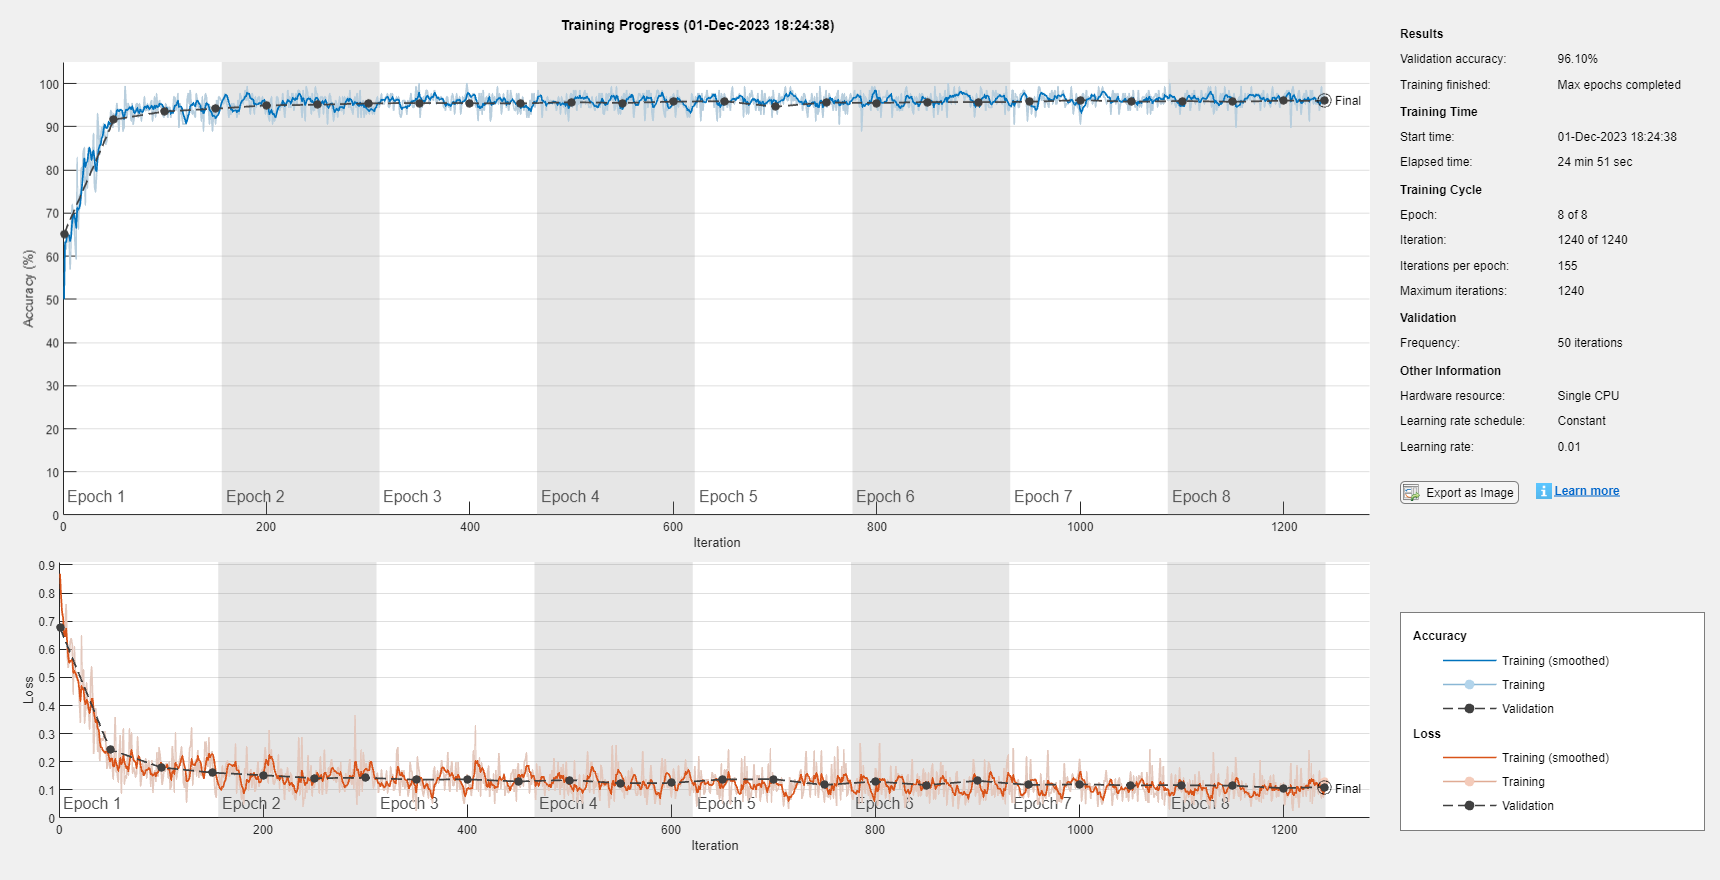

options = trainingOptions('sgdm','MaxEpochs', 8, 'MiniBatchSize', 128, ...
    'ValidationData', img_valid, ...
    'Shuffle', 'every-epoch', ...
    'ValidationFrequency', 50, ...
    'Plots', 'training-progress', ...
    'ValidationPatience', 4);

% Train the Network
net = trainNetwork(img_train, layers, options);

### Testing

The performance of the network on the test set is now studied by comparing the predicted labels and actual labels. A confusion matrix and ROC curve are generated to further study the precision, recall, false positive rate, and true positive rate.

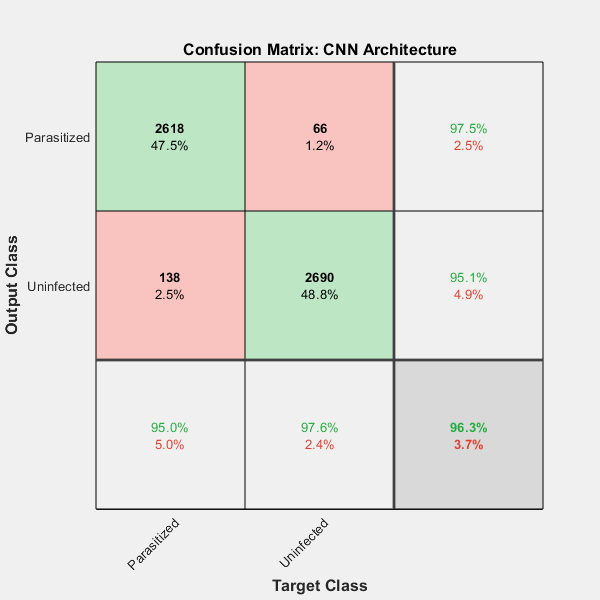

% Predict Test Labels using classify command
[predicted_labels, posterior] = classify(net, img_test);

% Actual Labels
actual_labels = img_test.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels, predicted_labels)
title('Confusion Matrix: CNN Architecture');


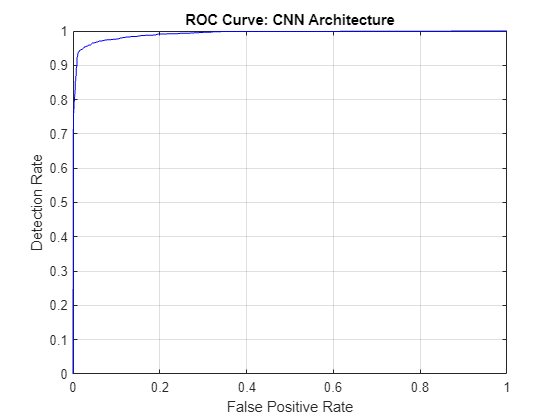

test_labels = double(nominal(img_test.Labels));

% ROC Curve - Our target class is the first class in this scenario.
[fp_rate, tp_rate, T, AUC] = perfcurve(test_labels, posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
title('ROC Curve: CNN Architecture')
xlabel('False Positive Rate');
ylabel('Detection Rate');


% Area under the ROC value
AUC

AUC = single
0.9919

## CNN Architecture with Preprocessing

Contrast enhancement is now applied to the same datasets before being fed into the CNN to study its effects on clasification performance. There are three types of contrast adjustment via luminosity supported within MATLAB: '**imadjust**', '**histeq**', '**adapthiseq**'. **Contrast-Limited Adaptive Histogram Equalization**('**adapthiseq**') is applied to the datatsets for reasons specified below.

### Why Contrast-Limited Adapative Historgram Equalization?

- '**imadjust**' does not significantly change the input image supplied when the RGB values are relatively spaced out between 0 and 255- not effective in these cases.

- '**histeq**' always substantially changes the input image regardless of its range in RGB values. However, histogram equalization is likely to oversaturate certain areas on images, which could hurt classification performance.

- '**adapthisteq**' performs histogram equalization on small sections of the image at at a time. It is chosen for preprocessing as it allows for parts of the image to stay at the same level of brightness while enhancing the contrast in others where it would be desired. This flexibility is desirable.

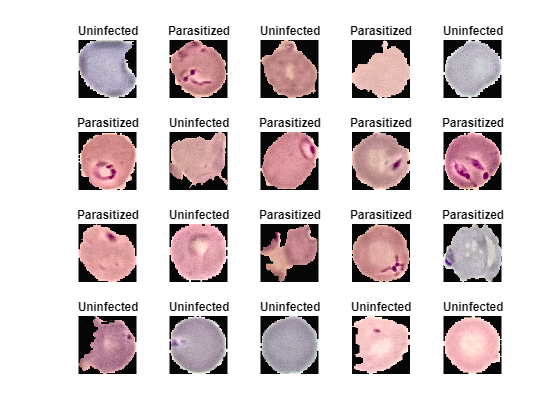

% Visualize the same images, but preprocessed
figure;

for idx=1:20
 subplot(4,5,idx);
 imshow(preprocess_malaria_images(img_train.Files{perm(idx)}, [200 200]))
 title(sprintf('%s',img_train.Labels(perm(idx))))
end


% Utilize recommended augmentedImageDatastore for faster
% resizing/transforming whilst preprocessing
img_train.ReadFcn=@(filename)preprocess_malaria_images(filename, [layers(1).InputSize(1), layers(1).InputSize(2)]);
img_valid.ReadFcn=@(filename)preprocess_malaria_images(filename, [layers(1).InputSize(1), layers(1).InputSize(2)]);

### Training

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:21 |       59.38% |       59.62% |       0.7980 |       0.8208 |          0.0100 |
|       1 |          50 |       00:02:06 |       88.28% |       90.43% |       0.2632 |       0.2458 |          0.0100 |
|       1 |         100 |       00:03:53 |       95.31% |       93.92% |       0.1906 |       0.1722 |          0.0100 |
|       1 |         150 |       00:05:39 |       92.97% |       94.69% |       0.1660 |   

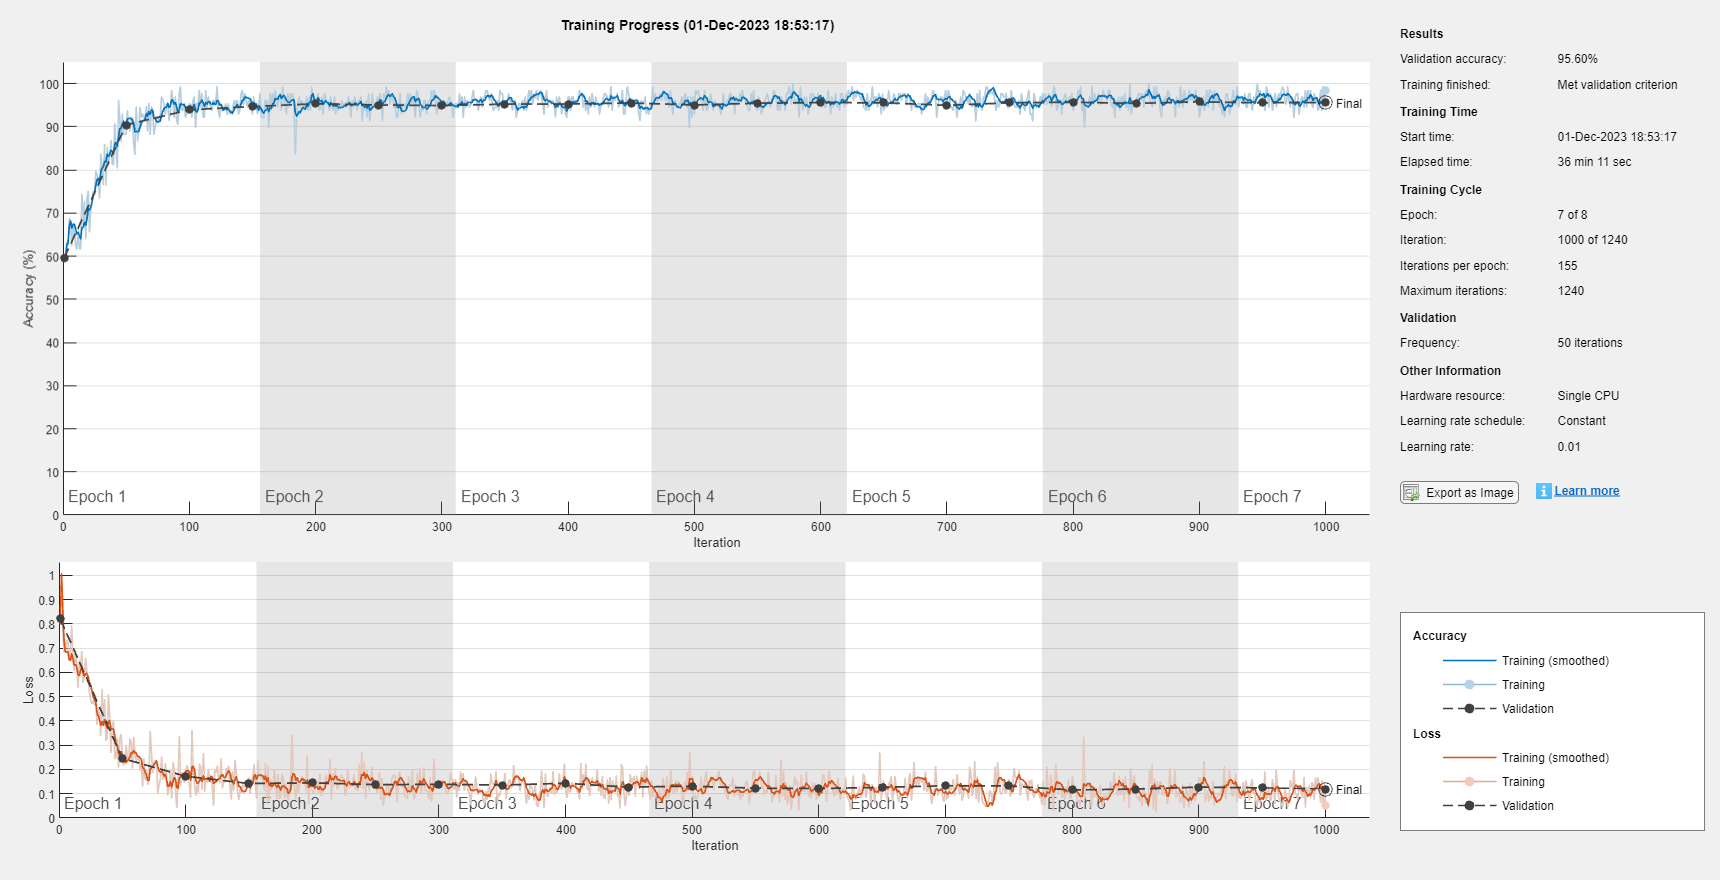

% Train the Preprocessed Network
net_preprocessed = trainNetwork(img_train, layers, options);

### Testing

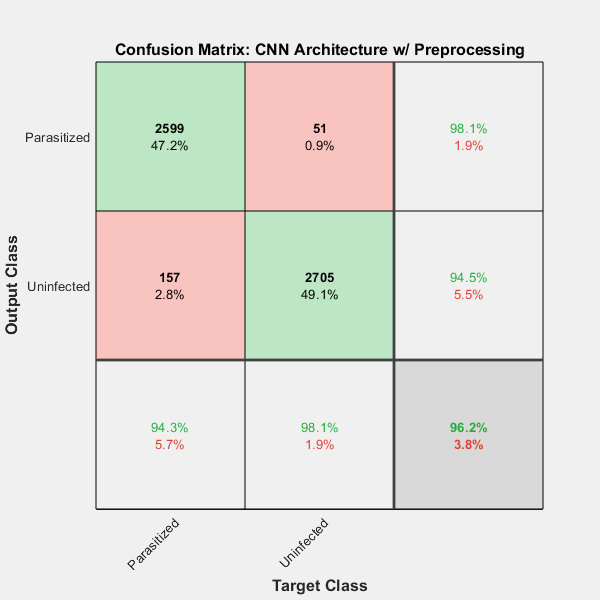

% Preprocess the test cases similar to the training
img_test.ReadFcn=@(filename)preprocess_malaria_images(filename, [layers(1).InputSize(1), layers(1).InputSize(2)]);

% Predict Test Labels using classify command
[predicted_labels, posterior] = classify(net_preprocessed, img_test);

% Confusion Matrix
figure;
plotconfusion(actual_labels, predicted_labels)
title('Confusion Matrix: CNN Architecture w/ Preprocessing');

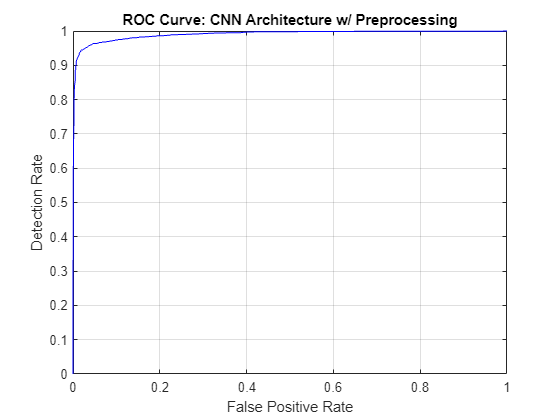


% ROC Curve - Our target class is the first class in this scenario.
[fp_rate, tp_rate, T, AUC] = perfcurve(test_labels, posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
title('ROC Curve: CNN Architecture w/ Preprocessing')
xlabel('False Positive Rate');
ylabel('Detection Rate');


% Area under the ROC value
AUC

AUC = single
0.9903

## CNN Architecture with Preprocessing and Data Augmentation

The set of images is now augmented by randomly being rotated up to ninety degree in either direction, and ocassionally reflected across the x-axis and/or y-axis. These augmentations are chosen as they can move where the parasite can appear in parasitized images and make the network more resilient to detecting unique shapes and occurances of parasites. These augmentations do not have the ability of cropping out the parasite, which is important as to not deter the accuracy.

% Data Augmentation (Ref: https://www.mathworks.com/help/deeplearning/ref/imagedataaugmenter.html)

% Configure a set of preprocessing options for image augmentation
% 'RandRotation': Rotates the image anywhere between -90 and 90 degrees
% 'RandXReflection': 50 % chance of flipping the image about the x-axis
% 'RandYReflection': 50 % chance of flipping the image about the y-axis
image_augumenter=imageDataAugmenter('RandRotation', [-90 90], 'RandXReflection', true,'RandYReflection', true);

aug_img_train_datastore = augmentedImageDatastore(img_size, img_train,'DataAugmentation', image_augumenter);
aug_img_valid_datastore = augmentedImageDatastore(img_size, img_valid,'DataAugmentation', image_augumenter);

### Training

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:21 |       46.88% |       60.44% |       0.9084 |       0.7711 |          0.0100 |
|       1 |          50 |       00:02:07 |       84.38% |       85.30% |       0.3280 |       0.3196 |          0.0100 |
|       1 |         100 |       00:03:54 |       98.44% |       92.92% |       0.1026 |       0.1882 |          0.0100 |
|       1 |         150 |       00:05:42 |       94.53% |       94.69% |       0.1492 |   

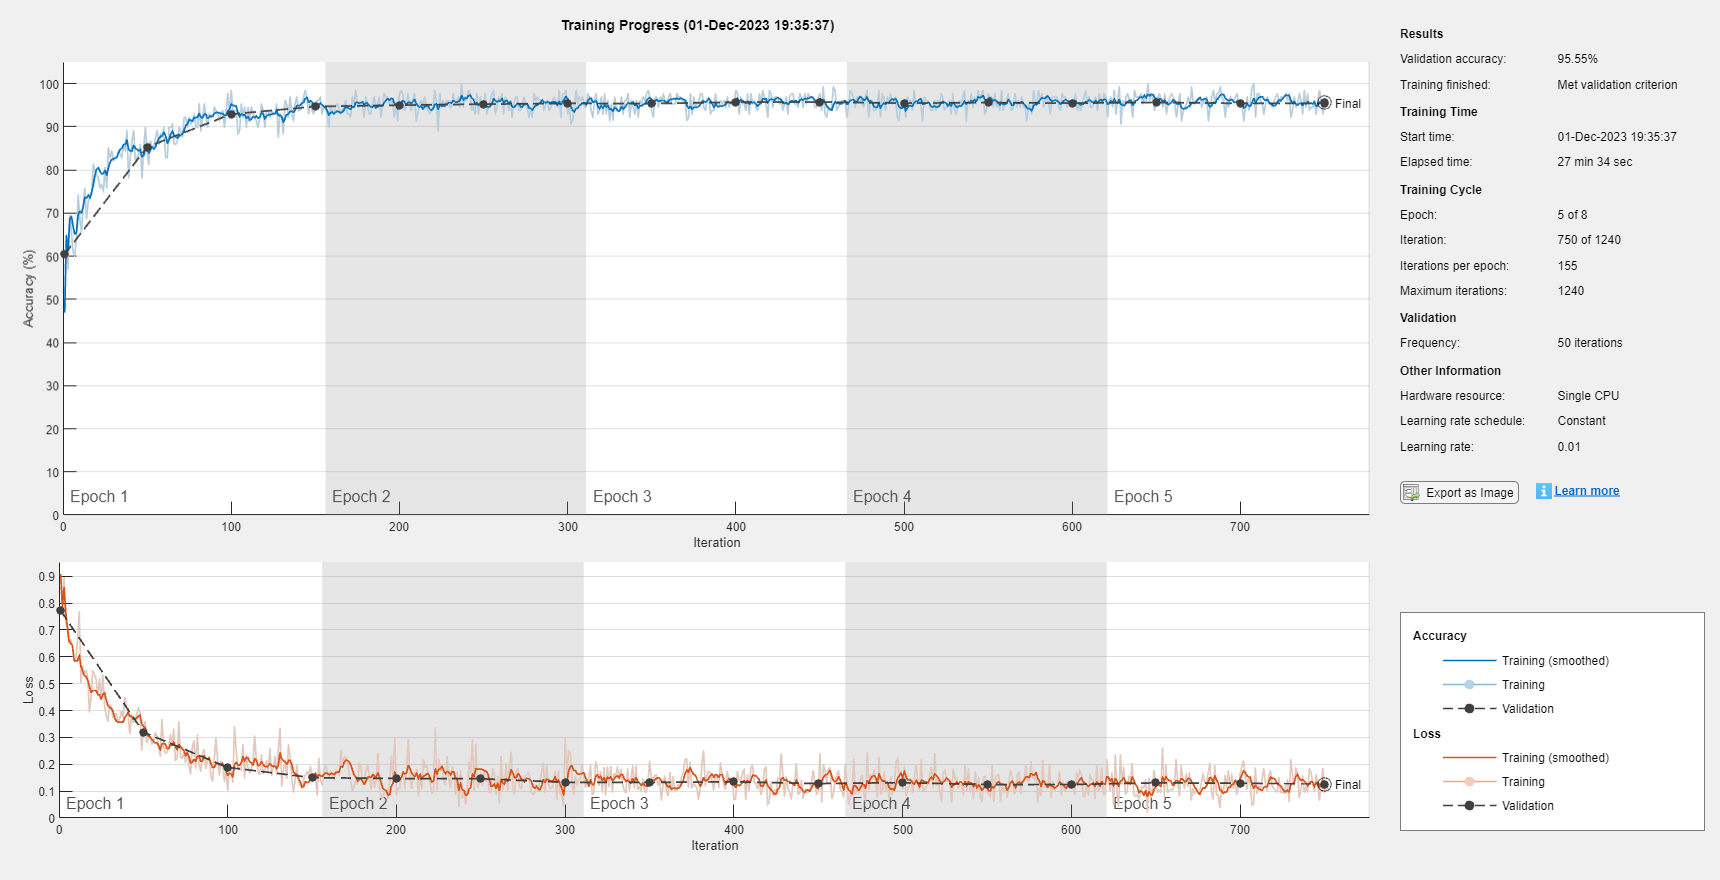

% Train the Preprocessed and Augmented Network
net_preprocessed_augmented = trainNetwork(aug_img_train_datastore, layers, options);

### Testing

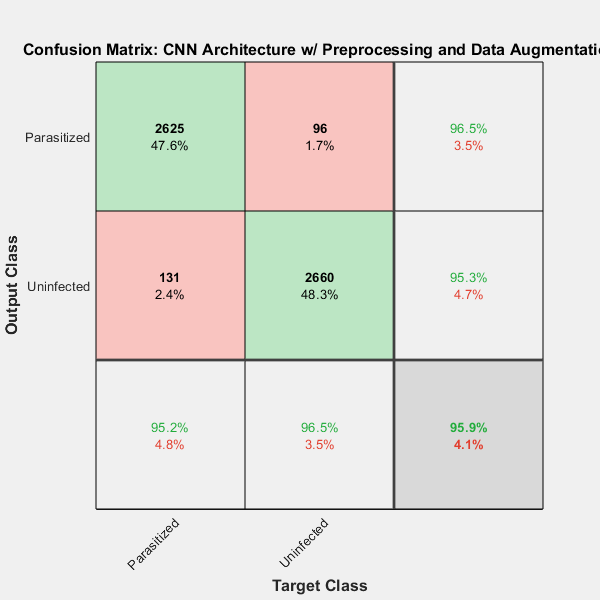

% Augment the test cases similar to the training
aug_img_test_datastore = augmentedImageDatastore(img_size, img_test,'DataAugmentation', image_augumenter);

% Predict Test Labels using classify command
[predicted_labels, posterior] = classify(net_preprocessed_augmented, img_test);

% Confusion Matrix
figure;
plotconfusion(actual_labels, predicted_labels)
title('Confusion Matrix: CNN Architecture w/ Preprocessing and Data Augmentation');


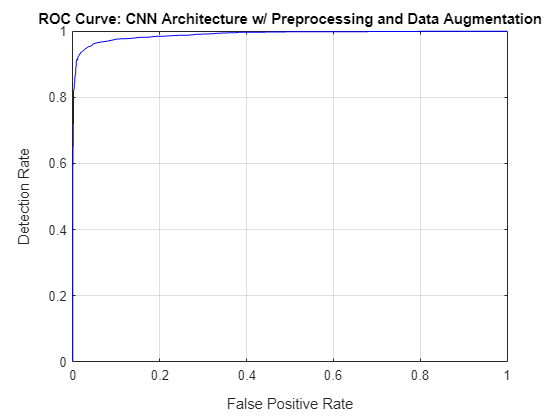

% ROC Curve - Our target class is the first class in this scenario.
[fp_rate, tp_rate, T, AUC] = perfcurve(test_labels, posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
title('ROC Curve: CNN Architecture w/ Preprocessing and Data Augmentation')
xlabel('False Positive Rate');
ylabel('Detection Rate');


% Area under the ROC value
AUC

AUC = single
0.9904

## Results & Suggestions for Improvement

**Note**: Although the number of epochs the network was set to run for was 8 in all of 3 cases, the training finished early after having 'Met validation criterion' in 2 of the 3 cases, irregardless of what epoch it was currently on or the total time spent training. This is why the network finished training after 7 and 5 epochs for the preprocessed and preprocessed and augmented datsets respectively.

All three types of input data achieved between a respectable 95 - 97% accuracy on each indivial subset. The very slight drop in validation and test accuracy after going from no preprocessing to preprocessing and preprocessing to augmented reveals that a better preprocessing function could have been chosen, and that data could likely have been augmented in more meaningful ways.

Also notable is the ~2.5% jump in training accuracy after preproccessing. Despite this increase, the preprocessed data had a much bigger gap between its training accuracy and validation accuracy comapred to the dataset without preprocessing. This is indicative of overfitting on the training data, which is further supported by the preprocessed and augmented data having a lower AUC. This overfitting could be combatted by decreasing the number of fullyConnected layers and/or increasing the dropout within the CNN. 

## Reshape Function

function [Iout] = reshape_image(filename,image_size)
% This function resizes all images to a fixed size
%
% Author: Barath Narayanan
% Date: 11/16/2021
%

% Read the images
I=imread(filename);

% Output Image
Iout=imresize(I,image_size);

end

## Preprocessing Function

function I_adapthisteq = preprocess_malaria_images(filename, desired_size)

% This function preprocesses malaria images using contrast enhancement and
% resizes the image
% Author: Connor Prikkel
% Ref: https://www.mathworks.com/help/images/contrast-enhancement-techniques.html

% Read the Image
I = imread(filename);

% Some images might be grayscale, replicate the image 3 times to
% create an RGB image.

if ismatrix(I)
  I = cat(3,I,I,I);
end

% Convert the image from RGB color space to L*a*b* color space
I_lab = rgb2lab(I);

% Values of luminosity span a range from 0 to 100 
% Scale values to range [0 1]
max_luminosity = 100;
L = I_lab(:,:,1)/max_luminosity;


% Contrast-Limited Adaptive Histogram Equalization - operates on small
% sections of the intensity image at a time
I_adapthisteq = I_lab;
I_adapthisteq(:,:,1) = adapthisteq(L)*max_luminosity;
I_adapthisteq = lab2rgb(I_adapthisteq);

% Resize the image
I_adapthisteq = imresize(I_adapthisteq, [desired_size(1) desired_size(2)]);

end